# Демодуляция ЧМ-сигналов

# Phase Differentiation Detector

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Phase Differentiation Detector

Наиболее популярным цифровым способом демодуляции частотно-модулированного сигнала является приемник на основе Delay Line Detector. Однако, он имеет один недостаток. Для его реализации необходимо находить аргумент комплексного числа. Обычно для этого нужно вычислять арктангенс, что явялется дорогостоящей операцией с точки зрения аппаратуры. 

Другой способ демодуляции, не требующий находить арктангенс числа, основывается на вычислении производной от фазы: Phase Differentiation Detector.

Будем считать, что прием сигнала осуществляется квадратурным способом. Тогда принятый комплексный отцированный сигнал можем представить в виде:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} =A_с \cdot \exp^{j\cdot \theta \left(t\right)} \ldotp$$


Фазу сигнала $s\left(t\right)$ можно рассчитать следующим образом:


$$\theta \left(t\right)=\mathrm{atan}\left(\frac{\mathrm{Im}\left\lbrace s\left(t\right)\right\rbrace }{\mathrm{Re}\left\lbrace s\left(t\right)\right\rbrace }\right)=\mathrm{atan}\left(\frac{s_i \left(t\right)}{s_r \left(t\right)}\right)=\mathrm{atan}\left(x\right),$$


где $\mathrm{Re}\left\lbrace s\left(t\right)\right\rbrace =s_r \left(t\right)$ и $\mathrm{Im}\left\lbrace s\left(t\right)\right\rbrace =s_i \left(t\right)$- действительная и мнимая часть сигнала.

Вычислим в явном виде производную от фазы $\theta \left(t\right)$:


$$\frac{d}{\mathrm{dt}}\theta \left(t\right)=\frac{1}{1+x^2 }\cdot \frac{\mathrm{dx}}{\mathrm{dt}}=\frac{s_r^2 \left(t\right)}{s_r^2 \left(t\right)+s_i^2 \left(t\right)}\cdot \frac{d}{\mathrm{dt}}\frac{s_i \left(t\right)}{s_r \left(t\right)}=\frac{s_r^2 \left(t\right)}{s_r^2 \left(t\right)+s_i^2 \left(t\right)}\cdot \frac{s_i \left(t\right)s_r^, \left(t\right)-s_r \left(t\right)s_i^, \left(t\right)}{s_r^2 \left(t\right)}=$$



$$=\frac{s_i \left(t\right)s_r^, \left(t\right)-s_r \left(t\right)s_i^, \left(t\right)}{s_r^2 \left(t\right)+s_i^2 \left(t\right)}=\frac{s_i \left(t\right)s_r^, \left(t\right)-s_r \left(t\right)s_i^, \left(t\right)}{{\left|s\left(t\right)\right|}^2 }\cdot$$


Заметим, что числитель дроби можно выразить через произведение комплексного сигнала и его производной в следующем виде:


$$\frac{d}{\mathrm{dt}}\theta \left(t\right)=\frac{\mathrm{Im}\left\lbrace s^* \left(t\right)\cdot s^{\prime } \left(t\right)\right\rbrace }{{\left|s\left(t\right)\right|}^2 },$$


где $s^{\prime } \left(t\right)$ - производная комплексного сигнала, $s^* \left(t\right)$ - сопряженный сигнал.

Подставим в предыдущее уравнение полное выражение для фазы сигнала и получим:


$$\frac{d}{\mathrm{dt}}\left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)=2\pi f_с +2\pi K_f \cdot m\left(t\right)=\frac{\mathrm{Im}\left\lbrace s^* \left(t\right)\cdot s^{\prime } \left(t\right)\right\rbrace }{{\left|s\left(t\right)\right|}^2 }\ldotp$$


После переноса слагаемых можем записать окончательный результат:


$$K_f \cdot m\left(t\right)=\frac{1}{2\pi }\cdot \frac{\mathrm{Im}\left\lbrace s^* \left(t\right)\cdot s^{\prime } \left(t\right)\right\rbrace }{{\left|s\left(t\right)\right|}^2 }-f_с \ldotp$$


Таким образом, Phase Differentiation Detector позволяет получит масштабированную копию информационного сообщения без вычисления операции арктангенса. Схема приемного устройства имеет вид:

### 2. Демодуляция аудиосообщения

Рассмотрим демодуляцию аудиосообщения с помощью скрипта, реализующего Phase Differentiation Detector.

В файлах Audio_FM_ModIdx_*.wav записан частотно-модулированный сигнал с различными индексами модуляции. Частота несущей $f_s$ равна 100 kHz, а частота дискретизации $f_s$ = $441$ kHz. Считаем, что прием выполняется квадратурным способ, то есть сигнал имеет вид:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Для демодуляции информационного сообщения нам необходимо вычислить значение следующей дроби:


$$\frac{d}{\mathrm{dt}}\theta \left(t\right)=\frac{\mathrm{Im}\left\lbrace s^* \left(t\right)\cdot s^{\prime } \left(t\right)\right\rbrace }{{\left|s\left(t\right)\right|}^2 },$$


Для этого сначала приближенно находим производные действительной и мнимой части с помощью вычисления разности между соседними отсчетами. Для этого задерживаем полученную пачку на один отсчет и вычитаем ее из текущей пачки отсчтетов. Далее находим комплексное сопряжение отсчета, умножаем его на производную и берем мнимую часть. Так мы получаем числитель дроби. Далее находим знаменатель, вычисляя квадрат модуля от текущих отсчетов сигнала.

Таким образом, вы получили производную от фазы. После удаления постоянной составляющей и децимации получаем восстановленное масштабированное аудиосообщение.

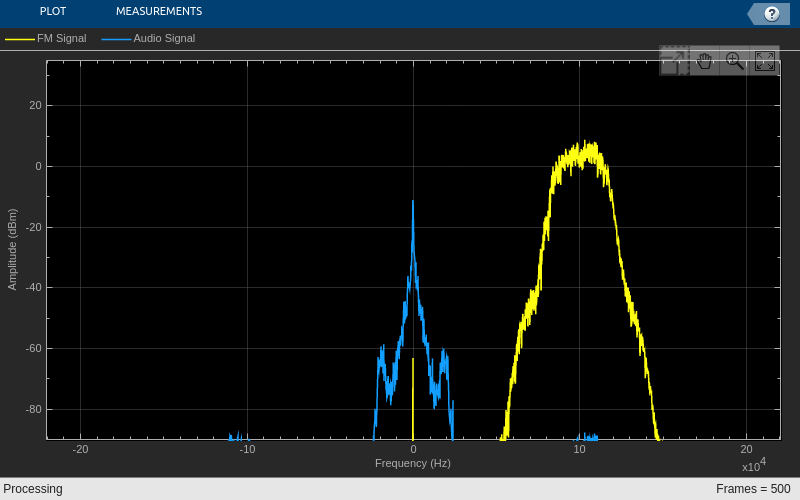

clc; clear; close all;

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
AudioAmp = 0.7;                   % коэффициент усиления аудиосигнала
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
ModIndex = '1';   % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% задержка на один отсчет 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1) + 1j*FmSignal(:,2);
    
    % вычисление производной от фазы
    FmSignalDiff  = FmSignal - DelayBlock(FmSignal);
    Num = imag(FmSignalDiff .* conj(FmSignal));
    Denum = abs(FmSignal).^2;
    PhaseDiff = Num ./ Denum;
    
    % убираем постоянную составляющую
    PhaseDiff = PhaseDiff - mean(PhaseDiff);
    
    % понижение частоты дискретизации
    AudioSignal = DownSampler(PhaseDiff);
    
    % формирование итогового сллбщения
    Message = [Message; AudioAmp * AudioSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal PhaseDiff]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме желтым показан спектр частотно-модулированного сигнала, а синим - спектр восстановленного сообщения.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что сообщение восстанавливается без искажений.

### 3. Демодуляция FM-радио в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. Входной сигнал проходит через фильтр нижных частот для выделения нужной радиостанции. Отфильтрованный сигнал поступает на Phase Differentiation Detector. В заключение сигнал децимируется, у него удаляется постоянная составляющая и он подается на звуковую карту. 

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
FcShift = 200e3;             % частота сдвига после фильтрации
AudioAmp = 0.1;              % коэффициент усиления аудиосигнала

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% задержка на один отсчет 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
    % вычисление производной от фазы
    FilteredDatalDiff = FilteredData - DelayBlock(FilteredData);
    Num = imag(FilteredDatalDiff .* conj(FilteredData));
    Denum = abs(FilteredData).^2;
    PhaseDiff = Num ./ Denum;
    
    % удаляем постоянную составляющую
    PhaseDiff = PhaseDiff - mean(PhaseDiff);
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(PhaseDiff);
    
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 4. Демодуляция FM-радио в Simulink

В файле FM_SDR_Receiver_Phase_Differentiation.slx представлена Simulink-модель, позволяющая прослушивать FM-радио с помощью RTL-SDR. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

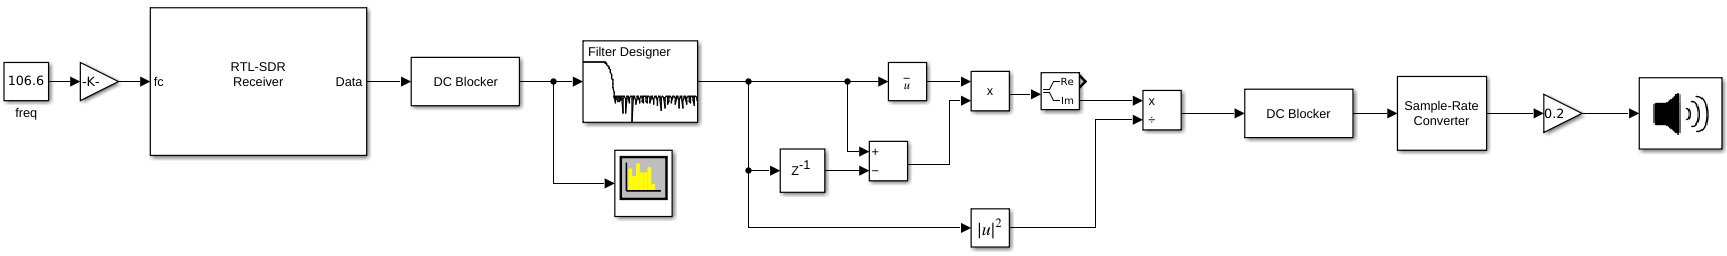

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR